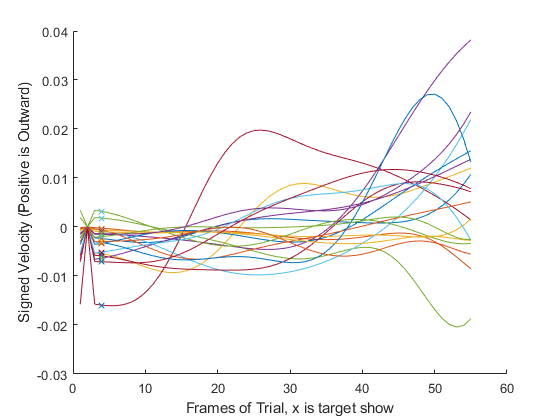

cd('E:\Documents\Google Drive\Preferred Mass')
if ~exist('Data')
    load('Data-OrderedwithFML.mat')
end
counter = 0;
figure(1);clf(1);

for subj = 1:nsubj
    for c = 1:nc
        for i = 50:150
            
            w4m = MT{c,subj}.robotstates.wait4mvt(i);
            if mean(Data{c,subj}.v_sign(w4m:w4m+15,i)) < 0 && rand > .99
                figure(1);hold on;
                plot(Data{c,subj}.v_sign(1:w4m+51,i))%(-w4m:1:30),
                plot(w4m,Data{c,subj}.v_sign(w4m,i),'x');
                counter = counter + 1;
            end
            if counter == 20;
                break
            end
        end
        if counter == 20;
            break
        end
    end
    if counter == 20;
        break
    end
end
xlabel('Frames of Trial, x is target show');
ylabel('Signed Velocity (Positive is Outward)');

cd('E:\Documents\Google Drive\Preferred Mass');
% savefig('resample_absolute_negatives.fig');